clear 
clc
co2_f = [ 1.5 2.5].*(60/22.4); % flow rate in mole/hour
co2 = [ 1.5 2.5];
t = [10 20 30]./60; % time

%%%%%%%%%%%%%%%%%%%% ac for absorption column 

NaOH_f = 10;
conc_inlet = 1.5;
V1_a1= [13.2 13.3 13.6];
V2_a1=[15.9 15.8 15.9];
V3_a1 = V2_a1-V1_a1; % titre reading for only HCO3- formed
V4_a1 = V1_a1- V3_a1; % effective reading only for NaOH
V5_a1=10;
N1_a1=0.1 ;% for HCL
N2_a1 = N1_a1*V4_a1/V5_a1;
N2_a1 = N2_a1*10;
conc_outlet_a1 = N2_a1;
n_NaOH_reacted_a1 = (conc_inlet - conc_outlet_a1)*NaOH_f;
n_CO2_reacted_a1 = n_NaOH_reacted_a1/2;
yield_a1 = n_CO2_reacted_a1/co2_f(1)*100; % in percent

%%%%%%%%%%%%%%%%%
V1_a2= [12.1 12.5 12.4];
V2_a2=[16.7 16.9 16.4];
V3_a2 = V2_a2-V1_a2; % titre reading for only HCO3- formed
V4_a2 = V1_a2- V3_a2; % effective reading only for NaOH
V5_a2=10;
N1_a2=0.1 % for HCL

N1_a2 = 0.1000

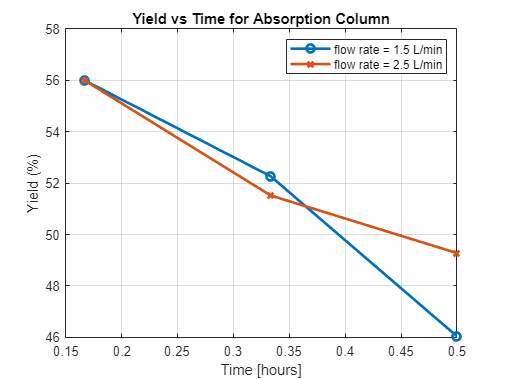

N2_a2 = N1_a2*V4_a2/V5_a2;
N2_a2 = N2_a2*10;
conc_outlet_a2 = N2_a2;
n_NaOH_reacted_a2 = (conc_inlet - conc_outlet_a2)*NaOH_f;
n_CO2_reacted_a2 = n_NaOH_reacted_a2/2;
yield_a2 = n_CO2_reacted_a2/co2_f(2)*100;

% by assumption that no HCO3- remains


%%%%%%%%%%%%%%%%%%%% bc for bubble column

conc_inlet = 1.5;
V=3;
V1_b1= [14.9 14.8 14.9];
V2_b1=[15.5 15.6 15.5];
V3_b1 = V2_b1-V1_b1; % titre reading for only HCO3- formed
V4_b1 = V1_b1- V3_b1; % effective reading only for NaOH
V5_b1=10;
N1_b1=0.1; % for HCL
N2_b1 = (N1_b1*V4_b1/V5_b1);
N2_b1 = N2_b1*10;
conc_outlet_b1 = N2_b1;
n_NaOH_reacted_b1 = (conc_inlet - N2_b1)*V;
n_CO2_reacted_b1 = n_NaOH_reacted_b1/2;
total_CO2_fed_b1 = t.*co2_f(1);
total_CO2_abs_b1 = t.*n_CO2_reacted_a1;
n_CO2_fed_t_b1 = (total_CO2_fed_b1-total_CO2_abs_b1);
yield_b1 =(n_CO2_reacted_b1./ n_CO2_fed_t_b1)*100;

avg_CO2_reacted_b1 = n_CO2_reacted_b1./t;

outlet_b1 = co2_f(1)-(avg_CO2_reacted_b1+n_CO2_reacted_a1);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

V1_b2= [14.5 14.8 14.7];
V2_b2=[15.3 15.6 15.3];
V3_b2 = V2_b2-V1_b2; % titre reading for only HCO3- formed
V4_b2 = V1_b2- V3_b2; % effective reading only for NaOH
V5_b2=10;
N1_b2=0.1 ;% for HCL
N2_b2 = N1_b2*V4_b2/V5_b2;
N2_b2 = N2_b2*10;
conc_outlet_b2 = N2_b2;
n_NaOH_reacted_b2 = (conc_inlet - N2_b2)*V;
n_CO2_reacted_b2 = n_NaOH_reacted_b2/2;
total_CO2_fed_b2 = t.*co2_f(2);
total_CO2_abs_b2 = t.*n_CO2_reacted_a2;
n_CO2_fed_t_b2 = (total_CO2_fed_b2-total_CO2_abs_b2);
yield_b2 =(n_CO2_reacted_b2./ n_CO2_fed_t_b2)*100;

avg_CO2_reacted_b2 = n_CO2_reacted_b2./t;
outlet_b2 = co2_f(2)-(avg_CO2_reacted_b2+n_CO2_reacted_a2);

%%%%%%% plots

plot(t,yield_a1,"-o",LineWidth=2)
hold on 
plot(t,yield_a2,"-x",LineWidth=2)
hold off
legend("flow rate = 1.5 L/min","flow rate = 2.5 L/min")
title("Yield vs Time for Absorption Column")
xlabel("Time [hours]")
ylabel("Yield (%)")
grid on

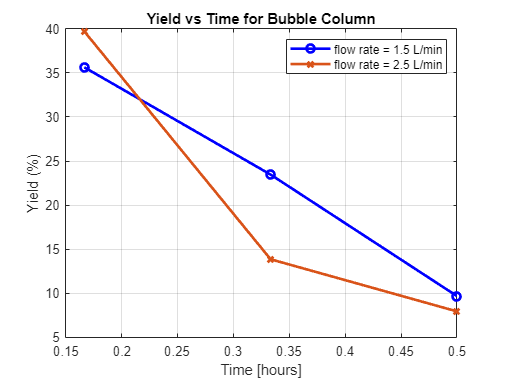


plot(t,yield_b1,"-o b",LineWidth=2)
hold on 
plot(t,yield_b2,"-x",LineWidth=2)
hold off
legend("flow rate = 1.5 L/min","flow rate = 2.5 L/min")
title("Yield vs Time for Bubble Column")
xlabel("Time [hours]")
ylabel("Yield (%)")
grid on

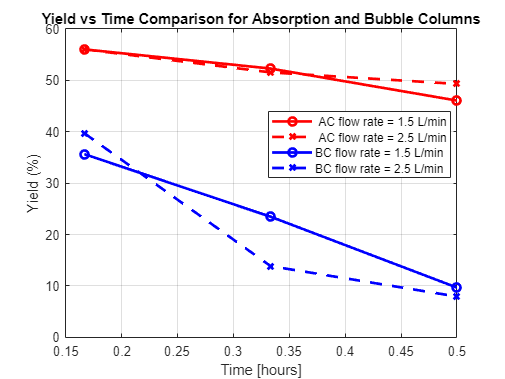


plot(t,yield_a1,"-o r",LineWidth=2)
hold on
plot(t,yield_a2,"--x r",LineWidth=2)
plot(t,yield_b1,"-o b",LineWidth=2)
plot(t,yield_b2,"--x b",LineWidth=2)
hold off
grid on
legend(" AC flow rate = 1.5 L/min"," AC flow rate = 2.5 L/min","BC flow rate = 1.5 L/min","BC flow rate = 2.5 L/min",Location="best")
title("Yield vs Time Comparison for Absorption and Bubble Columns")
xlabel("Time [hours]")
ylabel("Yield (%)")




% Writing to excel
filename='MT_304.xlsx';
T=table([1.5 1.5 1.5 2.5 2.5 2.5]',[t*60 t*60]',[V1_a1 V1_a2]', [V2_a1 V2_a2]', [conc_outlet_a1 conc_outlet_a2]', [n_NaOH_reacted_a1 n_NaOH_reacted_a2]', [n_CO2_reacted_a1 n_CO2_reacted_a2]', [1.5 1.5 1.5 2.5 2.5 2.5]'.*(60/22.4)', [yield_a1 yield_a2]' );
T.Properties.VariableNames = {'CO_2 Flow Rate (L/min)','Time (min)','HCl Volume (ml)(Phenolpthalein) (V1)','HCl Volume (ml)(Methyl Orange) (V2)','NaOH conc Outlet (M) (N2)','NaOH reacted (mol/h) ','CO_2 reacted (mol)','CO_2 fed (mol/h)', 'Yield (%)'}

T = 6×9 table
    CO_2 Flow Rate (L/min)    Time (min)    HCl Volume (ml)(Phenolpthalein) (V1)    HCl Volume (ml)(Methyl Orange) (V2)    NaOH conc Outlet (M) (N2)    NaOH reacted (mol/h)     CO_2 reacted (mol)    CO_2 fed (mol/h)    Yield (%)
    ______________________    __________    ____________________________________    ___________________________________    _________________________    _____________________    __________________    ________________    _________

             1.5                  10                        13.2                                   15.9                              1.05                        4.5                    2.25                4.0179           


writetable(T,filename,'Sheet','absorption column')

T2=table([1.5 1.5 1.5 2.5 2.5 2.5]',[t*60 t*60]',[V1_b1 V1_b2]', [V2_b1 V2_b2]', [conc_outlet_b1 conc_outlet_b2]', [n_NaOH_reacted_b1 n_NaOH_reacted_b2]', [n_CO2_reacted_b1 n_CO2_reacted_b2]', [n_CO2_fed_t_b1 n_CO2_fed_t_b2]', [yield_b1 yield_b2]' );
T2.Properties.VariableNames = {'CO_2 Flow Rate (L/min)','Time (min)','HCl Volume (ml)(Phenolpthalein) (V1)','HCl Volume (ml)(Methyl Orange) (V2)','NaOH conc Outlet (M) (N2)','NaOH reacted (mol/h) ','CO_2 reacted (mol)','CO_2 fed (mol/h)', 'Yield (%)'}

T2 = 6×9 table
    CO_2 Flow Rate (L/min)    Time (min)    HCl Volume (ml)(Phenolpthalein) (V1)    HCl Volume (ml)(Methyl Orange) (V2)    NaOH conc Outlet (M) (N2)    NaOH reacted (mol/h)     CO_2 reacted (mol)    CO_2 fed (mol/h)    Yield (%)
    ______________________    __________    ____________________________________    ___________________________________    _________________________    _____________________    __________________    ________________    _________

             1.5                  10                        14.9                                   15.5                              1.43                       0.21                   0.105               0.29464          


writetable(T2,filename,'Sheet','Bubble column')

T3=table([1.5 1.5 1.5 2.5 2.5 2.5]',[t*60 t*60]',[1.5*60/22.4 1.5*60/22.4 1.5*60/22.4 2.5*60/22.4 2.5*60/22.4 2.5*60/22.4]', [n_CO2_reacted_a1 n_CO2_reacted_a2]', [avg_CO2_reacted_b1 avg_CO2_reacted_b2]', [outlet_b1 outlet_b2]' );
T3.Properties.VariableNames = {'CO_2 Flow Rate (L/min)','Time (min)','CO_2 Flow Rate (mol/hr)','Absorbed in Column (mol/hr)','Average CO2 reacted in Bubble Column (mol/hr)','Outlet (mol/hr)'}

T3 = 6×6 table
    CO_2 Flow Rate (L/min)    Time (min)    CO_2 Flow Rate (mol/hr)    Absorbed in Column (mol/hr)    Average CO2 reacted in Bubble Column (mol/hr)    Outlet (mol/hr)
    ______________________    __________    _______________________    ___________________________    _____________________________________________    _______________

             1.5                  10                4.0179                        2.25                                    0.63                             1.1379     
             1.5                  20                4.0179                         2.1                                    0.45                             1.4679     
             1.5                  30                4.0179                        1.85                          

writetable(T3,filename,'Sheet','CO2 balance')
